# Initial setup file for the package

project_start;

## Choose a scenario and sensor configuration

#### MCity

Run this function if you are picking the MCity scenario. Else comment it out.

% [scenario,scenarioName,sensors]=loadMCity();
%%%

#### Other scenarios

Run these commands if you are picking a non-MCity scenario or creating your own. Else comment it out.

[allData, scenario, sensors,scenarioName]=choose_scenario(); %, it might error out and ask you add the new classes.

assignin('base','Ts', 0.05); % sampling time (0.05sec)
stopTime=allData(end).Time;
assignin('base','StopTime',stopTime); % simulation stop time (sec)

## Open DSD if needed to make changes

Open the Driving Scenario Designer App and import the chosen scenario. You should see "traffic_light" and "stop_sign" actors classes under the "Actors" section. If not, follow the 'scenarios' video to add these new actor classes. If you open the DSD before adding these classes

## Choose the start and end waypoints

% Prompt={'Enter the number of waypoints you want to specify'};
% num_of_wpts = str2double(inputdlg(Prompt,'Waypoint density'));
% [planner_wpts,ptLabels] = get_start_and_end_pts(scenario,num_of_wpts);
% SceneInfo = [planner_wpts,ptLabels];

load("SceneLabels.mat");

## Find number of traffic lights and stop signs

[TL_ID,stopSign_ID]=findActorID(scenario);
restart(scenario); 

## Setup required parameters for INS sensors and Vehicle Dynamics

load('BusActorState');
assignin('base','BusActorState', BusActorState);
load('BusINSMeas');
assignin('base','BusINSMeas', BusINSMeas);

scenarioLocation=append(fullfile(homedir,'scenarios',scenarioName),'.mat');
session=load(scenarioLocation);

## **Path Planning**

% % load('Part_of_MCity.mat');
% load('xpts.mat');
% load('ypts.mat');
% load('Mcity_Digraph.mat');
% load('edgesptsv1.mat');
% 
% % scenario = drivingScenario;
% % roadNetwork(scenario,'OpenDRIVE','minimcity.xodr');
% 
% 
% 
% plot(scenario);
% hold on
% p=plot(G,'XData',x,'YData',y,'EdgeColor','r','LineWidth',2,'MarkerSize',6,'NodeColor','r','ArrowSize',10);
% ylim([-100 150])
% xlim([-100 80])
% %view([0 90])
% 
% % Finding nearest edge and path selection
% [x1,y1] = getpts;
% 
% for j = 1:2 % 1 = starting point, 2 = destination
%     for q = 1:numnodes(G)%numedges(G)
%         NodeDist(q,j) = norm([x1(j)-x(q) y1(j)-y(q)]);
%     end
% end
% [val,indx] = sort(NodeDist,'ascend');
% for q = 1:length(indx)
%     if any(eq(G.Edges.EndNodes(:,1),indx(q,1)))
%         StartPoint = indx(q,1);
%         break
%     end
% end
% for q = 1:length(indx)
%     if any(eq(G.Edges.EndNodes(:,2),indx(q,2)))
%         EndPoint = indx(q,2);
%         break
%     end
% end
% 
% [OptPath,len] = shortestpath(G,StartPoint,EndPoint,'Method', 'positive');
% 
% highlight(p,OptPath,'EdgeColor','blue','LineWidth',4,'ArrowSize',10);
% plot(x1,y1,'x','color','g','MarkerSize',20,'linewidth',8);
% ylim([-100 150])
% xlim([-100 80])
% pause(1)
% 
% delete(p)
% 
% % waypoint concatanation
% xp=[];
% yp=[];
% for j=1:length(OptPath)-1
%     source=OptPath(j);
%     dest=OptPath(j+1);
% 
%     for i=1:length(edges)
%         if edges(i).source == source & edges(i).target==dest
% 
%             %concatination
%            xpoints=transpose(edges(i).x);
%            ypoints=transpose(edges(i).y);
% 
%            xp=[xp xpoints];
%            yp=[yp ypoints];
%         end   
%     end    
% end 
% 
% 
% hold on
% 
% plot(xp,yp,'-o','color','b','linewidth',2);
% plot(x1,y1,'x','color','g','MarkerSize',20,'linewidth',8);
% ylim([-100 150])
% xlim([-100 80])
% text(x1(1)-5,y1(1)-5,'Start','Color','red','FontSize',20);
% text(x1(2)-10,y1(2)+7,'Finish','Color','red','FontSize',20);
% %view([0 90])
% hold off

## Define Ego Vehicle Waypoints

ref=load('scenarios/Part_of_MCity.mat');
EgoWayPts=ref.data.ActorSpecifications.Waypoints

EgoWayPts =   -30.3000  -71.5000         0
  -30.4000  -62.5800    0.0100
  -30.4000  -54.4100    0.0100
  -30.4000  -38.4000         0
  -30.4000  -24.0000         0
  -30.6000  -10.5000         0
  -30.7000   -1.2300    0.0100
  -30.7700    9.3800    0.0100
  -30.7000   22.6000         0
  -30.8200   30.5400         0


% EgoWayPts = session.data.ActorSpecifications(1,1).Waypoints; % all other actor waypoints can be gotten the same way
%EgoWayPts = [xp' yp' zeros(length(xp),1)];
xRef = EgoWayPts(:,1);
yRef = -EgoWayPts(:,2);

## Define vehicle parameters used in the models

X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction


## Calculating reference pose vectors

**Based on how far the vehicle travels, the pose is generated using 1-D lookup tables.**

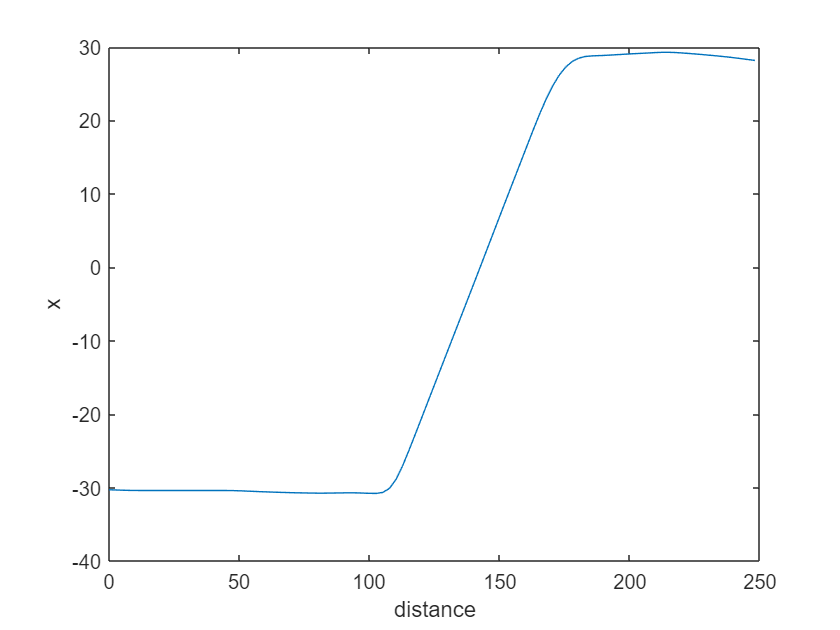

% calculate distance vector
distancematrix = squareform(pdist(EgoWayPts));
distancesteps = zeros(length(EgoWayPts)-1,1);
for i = 2:length(EgoWayPts)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
totalDistance = sum(distancesteps); % Total distance travelled [ x y C ] 200x4
distbp = cumsum([0; distancesteps]); % Distance for each waypoint
gradbp = linspace(0,totalDistance,100); % Linearize distance

% linearize X and Y vectors based on distance
xRef2 = interp1(distbp,xRef,gradbp);
yRef2 = interp1(distbp,yRef,gradbp);
yRef2s = smooth(gradbp,yRef2); % smooth waypoints
xRef2s = smooth(gradbp,xRef2); % smooth waypoints
% yRef2s = yRef2';
% xRef2s = xRef2';
figure
plot(gradbp,xRef2s)
xlabel('distance')
ylabel('x')

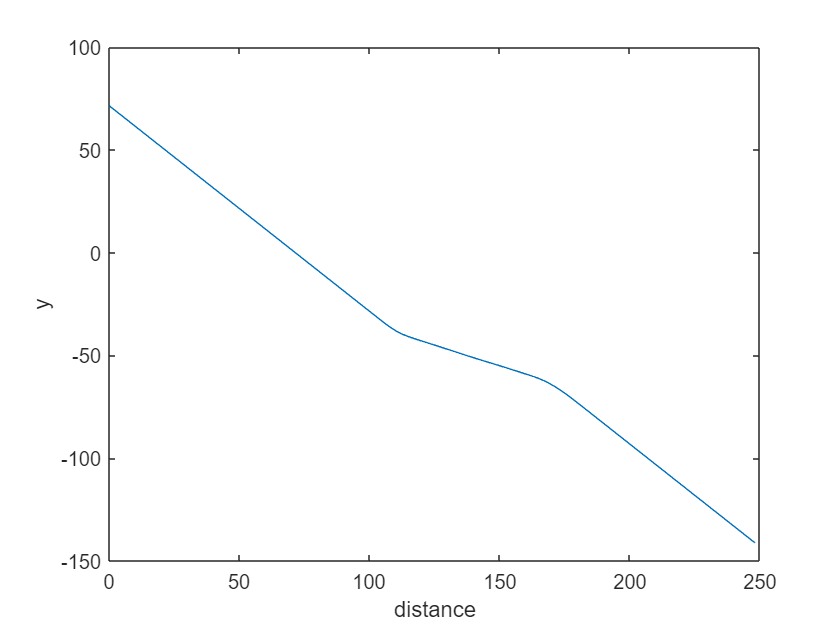

figure
plot(gradbp,yRef2s)
xlabel('distance')
ylabel('y')

## Calculate theta vector

**theta = orientation angle of the path at reference points **

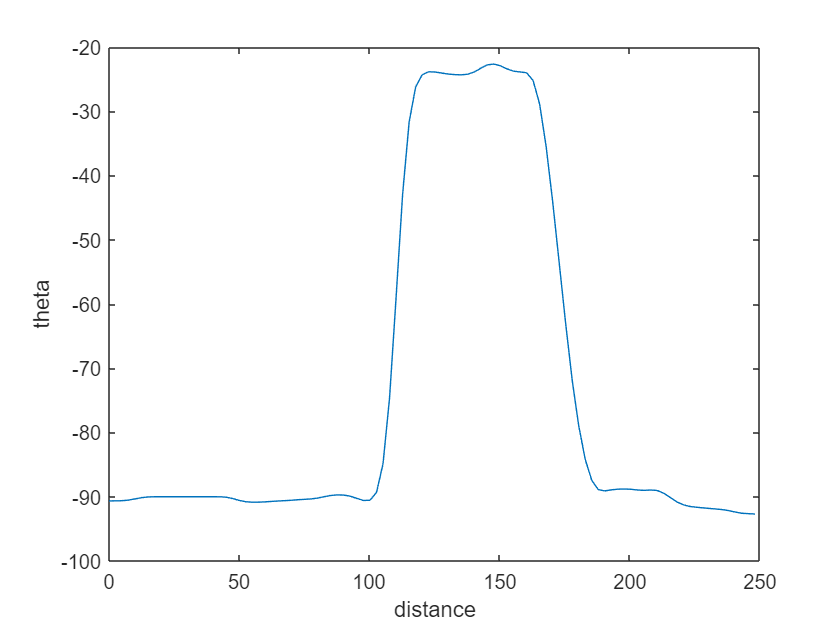

thetaRef = zeros(length(gradbp),1); 
for i = 2:length(gradbp)
    thetaRef(i,1) = atan2d((yRef2s(i)-yRef2s(i-1)),(xRef2s(i)-xRef2s(i-1)));
end
thetaRef(1) = thetaRef(2);
thetaRefs = smooth(gradbp,thetaRef); % smooth of theta
psi_o = thetaRefs(2)*(pi/180); % initial yaw angle
figure
plot(gradbp,thetaRefs)
xlabel('distance')
ylabel('theta')

## Create direction vector

direction = ones(length(gradbp),1);
EgoRefPose = [xRef2s,yRef2s,thetaRefs];

## Calculate curvature vector

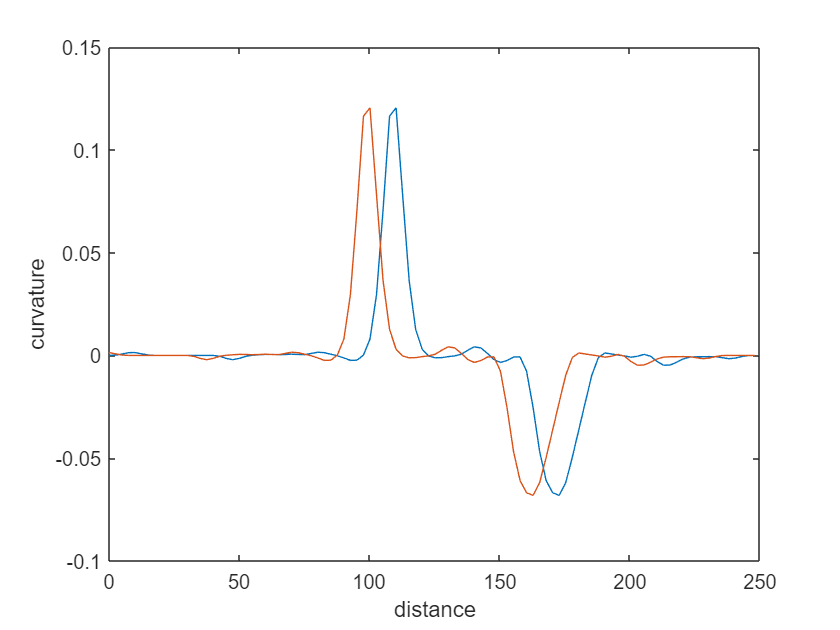

curvature = getCurvature(xRef2s,yRef2s);
curvature1 = curvature';
r = 1./abs(curvature1);
VelProfile = min(15,sqrt(9.81*r.*0.7));

curvatureAhd = zeros(1,length(curvature));
q = 5;
curvatureAhd(1:length(curvature) - q + 1) = curvature(q:end);
figure
plot(gradbp,curvature)
hold on
plot(gradbp,curvatureAhd)
hold off
xlabel('distance')
ylabel('curvature')

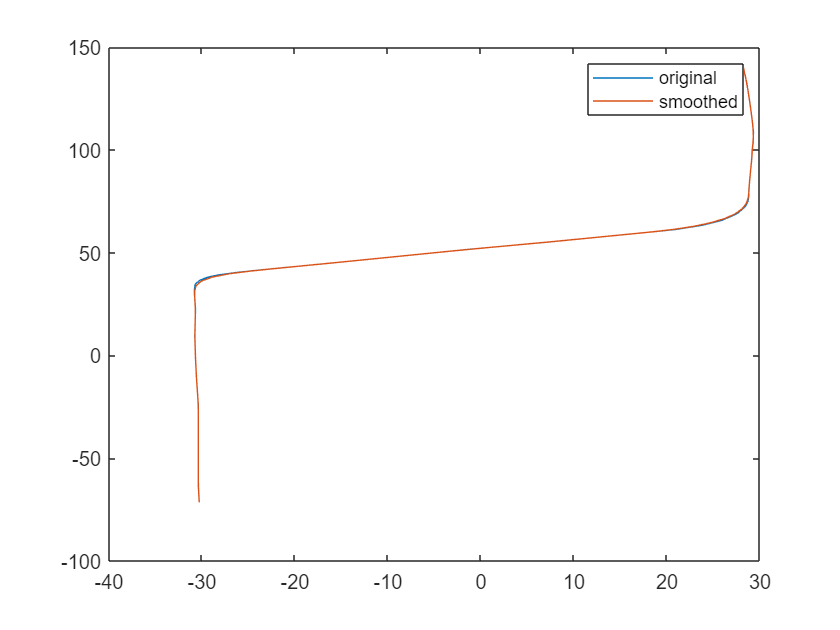

figure
plot(xRef,-yRef)
hold on
plot(xRef2s,-yRef2s)
hold off
legend('original','smoothed')

## Curvature Function

function curvature = getCurvature(xRef,yRef)
% Calculate gradient by the gradient of the X and Y vectors
DX = gradient(xRef);
D2X = gradient(DX);
DY = gradient(yRef);
D2Y = gradient(DY);
curvature = (DX.*D2Y - DY.*D2X) ./(DX.^2+DY.^2).^(3/2);
end